clearvars;close all;clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%DISPERZNí_MŘÍŽKA%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

l_mrizka = 50 * 10^-3; %vzdalenost mřížky od 0
d_mrizka = 20 * 10^-3;  %výška mřížky
alpha = 7;  %úhel natočení mřížky (CCW=+    ;   deg)
vryp_mm = 380;  %počet vrypů na mm

d = (1/vryp_mm)*10^(-3);    %mřížková konstanta [m]
mrizka_x = d_mrizka/2 * round(cos(pi/2 - deg2rad(alpha)),15);
mrizka_y = d_mrizka/2 * round(sin(pi/2 - deg2rad(alpha)),15);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%SENZOR_KAMERY%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

l_senzor = 100 * 10^-3; %vzdalenost senzoru kamery od 0

pix = 1.85 * 10^-6;  %rozměr pixelu kamery [m]
sensor_noo_pix = [4024 3036];   %Počet pixelů senzoru kamery [-]
sensor_dims = sensor_noo_pix*pix;    %rozměr sensoru kamery [m]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%RED_RAY%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

red_ray_pocatek = [0 0.008];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%VÝPOČTY%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
colors = [400 600 800 1000];


a = -(mrizka_y/mrizka_x);
rayVSgrid = [(red_ray_pocatek(2)+a*l_mrizka)/a red_ray_pocatek(2)];

beta(1) = asin((colors(1)*10^-9)/d + sin(deg2rad(alpha)));
beta_d(1) = rad2deg(beta(1));
beta(2) = asin((colors(2)*10^-9)/d + sin(deg2rad(alpha)));
beta_d(2) = rad2deg(beta(2));
beta(3) = asin((colors(3)*10^-9)/d + sin(deg2rad(alpha)));
beta_d(3) = rad2deg(beta(3));
beta(4) = asin((colors(4)*10^-9)/d + sin(deg2rad(alpha)));
beta_d(4) = rad2deg(beta(4))

beta_d =    15.8946   20.4793   25.2057   30.1238



rayVSsensor1 = [l_senzor tan(beta(1))*l_senzor+rayVSgrid(2)-tan(beta(1))*rayVSgrid(1)];
rayVSsensor2 = [l_senzor tan(beta(2))*l_senzor+rayVSgrid(2)-tan(beta(2))*rayVSgrid(1)];
rayVSsensor3 = [l_senzor tan(beta(3))*l_senzor+rayVSgrid(2)-tan(beta(3))*rayVSgrid(1)];
rayVSsensor4 = [l_senzor tan(beta(4))*l_senzor+rayVSgrid(2)-tan(beta(4))*rayVSgrid(1)];

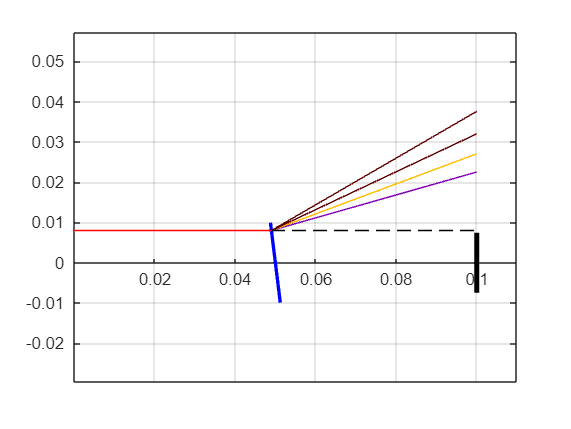

figure(1)
plot([l_mrizka-mrizka_x l_mrizka+mrizka_x],[mrizka_y -mrizka_y],'blue','LineWidth',2)
hold on
plot([l_senzor l_senzor],[sensor_dims(1) -sensor_dims(1)],'black','LineWidth',3)
plot([red_ray_pocatek(1) rayVSgrid(1)],[red_ray_pocatek(2) rayVSgrid(2)],'red')

plot([rayVSgrid(1) l_senzor],[rayVSgrid(2) rayVSsensor1(2)],'Color','#8300b5')
plot([rayVSgrid(1) l_senzor],[rayVSgrid(2) rayVSsensor2(2)],'Color','#ffbe00')
plot([rayVSgrid(1) l_senzor],[rayVSgrid(2) rayVSsensor3(2)],'Color','#610000')
plot([rayVSgrid(1) l_senzor],[rayVSgrid(2) rayVSsensor4(2)],'Color','#610000')
plot([rayVSgrid(1) l_senzor],[rayVSgrid(2) rayVSgrid(2)],'--k')
axis equal
grid on
set(gca, 'XAxisLocation', 'origin')
xlim([0 l_senzor+0.01])